# **Parrando's Paradox**

addpath ../dablab_files/dablab_repo/
latex_interpreter

#### Define chance parameters of each game along with the parameters of gameplay win/lose conditions

budget0 = 1;
bet = 0.01; 
maxTurns = 100000;
withdrawMin = budget0 + bet;
withdrawMax = 2*budget0;
withdraw = 2

withdraw = 2

num_games = 2; %number of distinct games to choose ...
%from every turn
def_play_prob = 1/num_games; %a default probability ...
% of selecting a particular game
strategy = 0; %0 for no strategy (random), 1 for best strategy BBABBA


#### Fix Game A Parameters

p_play_a = 0;
% p_win_a = 18/38
p_win_a = 0.5

p_win_a = 0.5000

p_lose_a = 1-p_win_a;

exp_a_any_distribution = bet*p_win_a - bet*p_lose_a

exp_a_any_distribution = 0

#### Fix Game B Parameters

p_play_b = 1 - p_play_a;
m = 3;
p_play_b1 = 1/m; 
p_play_b2 = 1- p_play_b1;

% p_win_b1 = 4/38, p_win_b2 = 27/38 %rigged games
p_win_b1 = 1/10, p_win_b2 = 3/4 %fair games

p_win_b1 = 0.1000

p_win_b2 = 0.7500

p_lose_b1  = 1-p_win_b1;
p_lose_b2 = 1-p_win_b2;

exp_b_uniform_distribution = ...
    p_play_b1*(bet*p_win_b1 - bet*p_lose_b1) + ...
    p_play_b2*(bet*p_win_b2 - bet*p_lose_b2)

exp_b_uniform_distribution = 6.6667e-04

#### Run the simulation

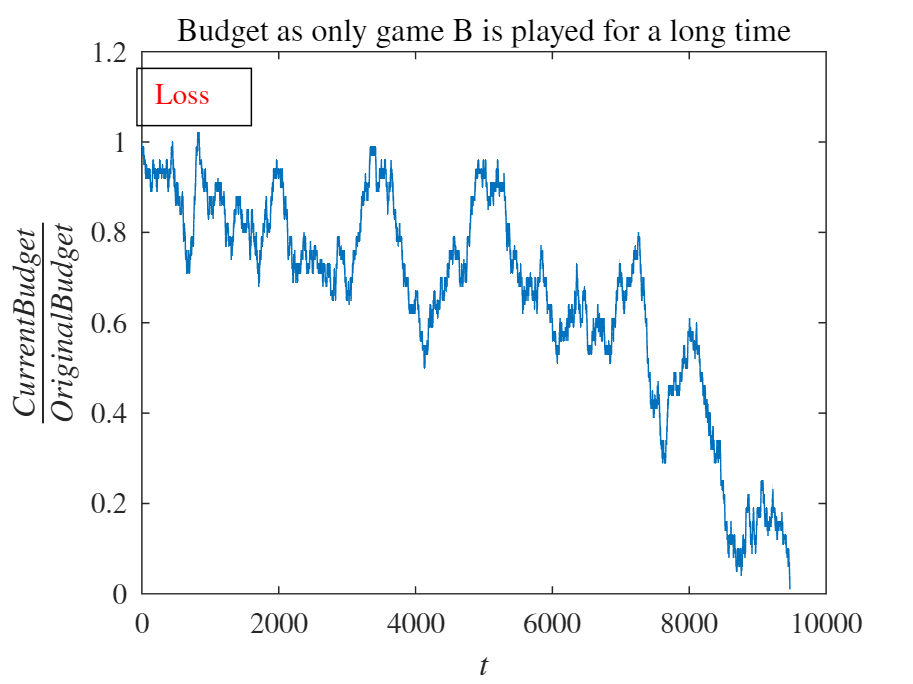

budgetArray = zeros(maxTurns,1);
budget = budget0;
budgetArray(1) = budget0;
turn = 1;
forceGameA = 0;
forceGameB = 0;

while budget >= bet && budget <= withdraw && turn < maxTurns
    turn =  turn + 1;
    if strategy == 1
        if mod(budget/bet, m) < 1
           forceGameA = true;
           forceGameB = false;
        else
           forceGameA = false; 
           forceGameB = true;
        end
    else
        choose_game = rand;
    end

    if (strategy && forceGameA) || (~strategy && choose_game <= p_play_a) %play game A
        budget = budget + play(p_win_a, bet);
    elseif (strategy && forceGameB) || (~strategy && choose_game <= p_play_a + p_play_b) %play game B
        if mod(budget/bet, m) < 1 %play game B1
            budget = budget + play(p_win_b1, bet);
        else %play game B2
            budget = budget + play(p_win_b2, bet);
        end
    end
    budgetArray(turn) = budget;
end

turns = 0:1:turn-1;


strLoss = 'Loss';
strGain = 'Gain';
strEqual = 'Evened out losses and gains';

if budget > budget0
    str = strGain;
    col = [0, 100, 0]/255;
elseif budget < budget0
    str = strLoss;
    col = 'red';
else
    str = strEqual;
    col = 'k';
end

figure('Name','Parrando''s Paradox in Action')
plot(turns, budgetArray(turns+1));

if strategy
    title(['Budget as games are selected ' ...
        'optimally']);
else
    if p_play_a ~= 0 && p_play_a ~= 1
        title('Budget as games are selected at random and played');
    elseif p_play_a == 1
        title('Budget as only game A is played for a long time');
    else
        title('Budget as only game B is played for a long time')
    end
end
xlabel('$t$');
ylabel('$\frac{Current Budget}{Original Budget}$');

dim = [0.15 .70 .20 .20];
a = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on');
a.Color = col;

A simple function to modify the budget as per a random throw with fixed probablity parameters

function change = play(p_win, bet)
    throw = rand;
    if throw <= p_win
        change = bet;
    else
        change = -bet;
    end
end